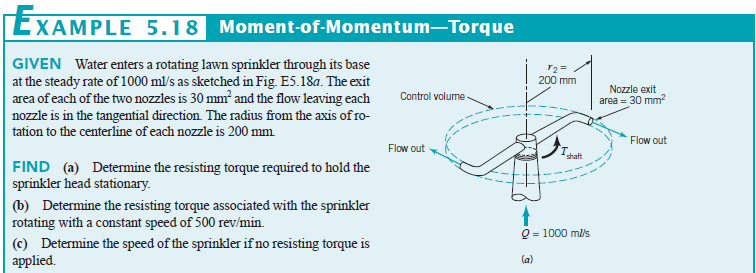

# constants

u = symunit;
rho = 999*u.kg/u.m^3;
Q = 1000*u.ml/u.s;
A = 30*u.mm^2;
r = 200*u.mm;
omega = 500*u.rpm;

# part A

## inflow properties

mdot1_a = rewrite(rho*Q, 'SI');

## outflow properties

syms V2_a V3_a;
mdot2_a(V2_a) = rewrite(rho*A*V2_a, 'SI');
mdot3_a(V3_a) = rewrite(rho*A*V3_a, 'SI');

## conservation of mass

eqn_a = sym.zeros(3,1);
eqn_a(1) = V2_a == V3_a;
eqn_a(2) = mdot1_a == formula(mdot2_a)+formula(mdot3_a);

## conservation of moment-of-momentum

syms Tshaft_a;
eqn_a(3) = Tshaft_a == mdot1_a*(-r*V2_a);

## solution

[Tshaft_a V2_a V3_a] = solve(eqn_a, [Tshaft_a V2_a V3_a]); %#ok
Tshaft_a = rewrite(Tshaft_a, u.N*u.m);
Tshaft_a_vpa = vpa(Tshaft_a) %#ok

$$Tshaft\_a\_vpa = -3.33\,N\,m$$

V2_a_vpa = vpa(V2_a, 4) %#ok

$$V2\_a\_vpa = 16.67\,\frac{m}{s}$$

V3_a_vpa = vpa(V3_a, 4) %#ok

$$V3\_a\_vpa = 16.67\,\frac{m}{s}$$

clear Tshaft_a_vpa V2_a_vpa V3_a_vpa;

# part B

## inflow properties

mdot1_b = rewrite(rho*Q, 'SI');

## outflow properties

W2_b = V2_a;
W3_b = V3_a;
U2_b = rewrite(omega, u.rad/u.s)*rewrite(r, 'SI')/u.rad;
U3_b = U2_b;
V2_b = W2_b-U2_b;
V3_b = W3_b-U3_b;

## conservation of moment-of-momentum

Tshaft_b = rewrite(mdot1_b*(-r*V2_b), u.N*u.m);
Tshaft_b_vpa = vpa(Tshaft_b, 3) %#ok

$$Tshaft\_b\_vpa = -1.24\,N\,m$$

clear Tshaft_b_vpa;

# part C

## inflow properties

mdot1_b = rewrite(rho*Q, 'SI');

## outflow properties

syms V2_b V3_b;
W2_b = V2_a;
W3_b = V3_a;
U2_b = rewrite(omega, u.rad/u.s)*rewrite(r, 'SI')/u.rad;
U3_b = U2_b;
V2_b = W2_b-U2_b;
V3_b = W3_b-U3_b;
mdot2_b = rewrite(rho*A*V2_b, 'SI');
mdot3_b = rewrite(rho*A*V3_b, 'SI');

## conservation of moment-of-momentum

Tshaft_b = rewrite(mdot1_b*(-r*V2_b), u.N*u.m);
Tshaft_b_vpa = vpa(Tshaft_b, 3) %#ok
clear Tshaft_b_vpa;